# Singular Configurations

clc; clear; close all;
load_data_kinematics;

## Minimization of the determinant of the jacobian matrix

[J_gripper_symb,~] = jac_symb_SING_CONFIG;

syms q1_sym q2_sym q3_sym l1a l1b l1c l2 l3 tilt_angle

numeric_vars = num2cell([L angle]);
J_grip_subs = subs(J_gripper_symb,{l1a l1b l1c l2 l3 tilt_angle},numeric_vars);

determinant = det(J_grip_subs);

eqn = abs(determinant);

eqn_MLF = matlabFunction(eqn,'Vars',{symvar(eqn)});

nVars = 3;
opt = optimoptions(@ga,'Display','off');

problem.fitnessfcn = eqn_MLF;
problem.nvars = nVars;
problem.solver = 'ga';
problem.options = opt;

nRuns = 10;
SOL = zeros(nRuns,nVars); F = zeros(nRuns,1); SOL_norm = zeros(nRuns,nVars);
for i = 1:nRuns
    [sol,fval] = ga(problem);
    
    if sol(3) >= 0
        if sol(1) >= 0
            sol_normalized = [mod(sol(1),2*pi)/pi sol(2) mod(sol(3),pi)/pi];
        else
            sol_normalized = [mod(sol(1),-2*pi)/pi sol(2) mod(sol(3),pi)/pi];
        end    
    else
        if sol(1) >= 0
            sol_normalized = [mod(sol(1),2*pi)/pi sol(2) mod(sol(3),-pi)/pi];
        else
            sol_normalized = [mod(sol(1),-2*pi)/pi sol(2) mod(sol(3),-pi)/pi];
        end 
    end
    
    SOL(i,:) = sol;
    F(i) = fval;
    SOL_norm(i,:) = sol_normalized;
    
end

## Check and plot results

idx_ok = abs(abs(SOL_norm(:,3))-0.5) < 0.01;
SOL_norm_filtered = SOL_norm(idx_ok,:);
F_filtered = F(idx_ok);
T = array2table([SOL_norm_filtered F_filtered]);
T.Properties.VariableNames = {'q1 [pi rad]','q2 [m]','q3 [pi rad]','determinant value'};
format short
disp(T);

    q1 [pi rad]     q2 [m]     q3 [pi rad]    determinant value
    ___________    ________    ___________    _________________

        0.6372     -0.60807      0.50516         0.00023296    
       -0.4764     -0.53793      -0.4969         4.1723e-05    
      -0.61986     -0.44277     -0.49972         2.5954e-05    
    0.00019529     -0.84101     -0.49589         0.00021875    
        0.4876     -0.65122     -0.49868         0.00010209    
       -1.7897     -0.60961       0.5019         8.3704e-05    
      -0.67681      -0.9673      0.49916         4.4912e-05    



SOL_plot = SOL_norm(idx_ok,:);
SOL_plot(:,1) = SOL_plot(:,1)*pi;
SOL_plot(:,2) = linspace(pos_limits(3),pos_limits(4),numel(F_filtered));
SOL_plot(:,3) = SOL_plot(:,3)*pi;
SOL_plot = num2cell(SOL_plot)';
disp(SOL_plot);

    {[2.0018]}    {[-1.4967]}    {[-1.9474]}    {[6.1352e-04]}    {[ 1.5318]}    {[-5.6225]}    {[-2.1263]}
    {[     0]}    {[ 0.0667]}    {[ 0.1333]}    {[    0.2000]}    {[ 0.2667]}    {[ 0.3333]}    {[ 0.4000]}
    {[1.5870]}    {[-1.5611]}    {[-1.5699]}    {[   -1.5579]}    {[-1.5666]}    {[ 1.5768]}    {[ 1.5681]}



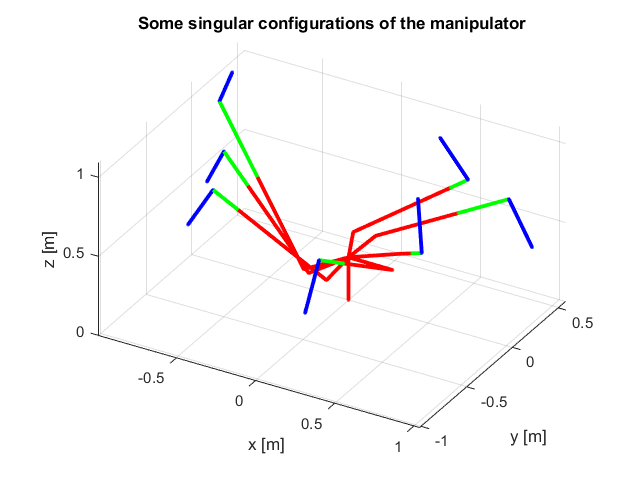

figure
for i = 1:numel(F_filtered)   
    plot_robot(SOL_plot(:,i),L,angle,gcf);
    hold on
end
grid on
axis equal
view(30,30)
xlabel('x [m]'); ylabel('y [m]'); zlabel('z [m]')
title('Some singular configurations of the manipulator')